% Analytic_strain_modeling3.mlx
%
% In Analytic_strain_modeling2.mlx, we learned that the observed interlayer displacement
% can be related back to the intralayer strain if there is no Moire twist involved.
% A necessary step was to invoke the small angle approximation; otherwise it doesn't work
% out at all. Now, we will investigate if this holds true with a small Moire.
%
% Nathanael Kazmierczak, 05/21/2020

syms tr tm x y
a1_0 = [x;y];
a2_0 = [x;y];
trxy = exp(-x^2-y^2)*tr;
rotmat_sm1 = [1, -tm/2; tm/2, 1];
rotmat_sm2 = [1, tm/2; -tm/2, 1];
rotmat_sr1 = [1, -trxy/2; trxy/2, 1];
rotmat_sr2 = [1, trxy/2; -trxy/2, 1];
a1sm = rotmat_sm1*a1_0;
a2sm = rotmat_sm2*a2_0;
a1sr = rotmat_sr1*a1sm;
a2sr = rotmat_sr2*a2sm;

u_observed_s = a1sr - a2sr

$$u\_observed\_s = \begin{array}{l} \left(\begin{array}{c} -\mathrm{tm}\,y-\frac{\mathrm{tr}\,\sigma_{1}\,\left(y-\frac{\mathrm{tm}\,x}{2}\right)}{2}-\frac{\mathrm{tr}\,\sigma_{1}\,\left(y+\frac{\mathrm{tm}\,x}{2}\right)}{2}\\ \mathrm{tm}\,x+\frac{\mathrm{tr}\,\sigma_{1}\,\left(x-\frac{\mathrm{tm}\,y}{2}\right)}{2}+\frac{\mathrm{tr}\,\sigma_{1}\,\left(x+\frac{\mathrm{tm}\,y}{2}\right)}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{-x^{2}-y^{2}} \end{array}$$

ua1s = a1sr - a1sm

$$ua1s = \left(\begin{array}{c} -\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y+\frac{\mathrm{tm}\,x}{2}\right)}{2}\\ \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x-\frac{\mathrm{tm}\,y}{2}\right)}{2} \end{array}\right)$$

ua2s = a2sr - a2sm

$$ua2s = \left(\begin{array}{c} \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y-\frac{\mathrm{tm}\,x}{2}\right)}{2}\\ -\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x+\frac{\mathrm{tm}\,y}{2}\right)}{2} \end{array}\right)$$

exx_observed_s = simplify(diff(u_observed_s(1),x))

$$exx\_observed\_s = 2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

exx_a1s = diff(ua1s(1),x)

$$exx\_a1s = \mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y+\frac{\mathrm{tm}\,x}{2}\right)-\frac{\mathrm{tm}\,\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{4}$$

exx_a2s = diff(ua2s(1),x)

$$exx\_a2s = -\frac{\mathrm{tm}\,\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{4}-\mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y-\frac{\mathrm{tm}\,x}{2}\right)$$

ratio = simplify(exx_observed_s/(exx_a1s-exx_a2s))

$$ratio = 1$$

## Investigate the other components

exy_observed_s = simplify(diff(u_observed_s(1),y));
exy_a1s = diff(ua1s(1),y)

$$exy\_a1s = \mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y+\frac{\mathrm{tm}\,x}{2}\right)-\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}$$

exy_a2s = diff(ua2s(1),y)

$$exy\_a2s = \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}-\mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(y-\frac{\mathrm{tm}\,x}{2}\right)$$

intralayer_sum = simplify(exy_a1s-exy_a2s)

$$intralayer\_sum = \mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(2\,y^{2}-1\right)$$

exy_observed_s

$$exy\_observed\_s = 2\,\mathrm{tr}\,y^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}-\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}-\mathrm{tm}$$

ratio = simplify((exy_observed_s+tm)/(exy_a1s-exy_a2s))

$$ratio = 1$$

% So under the small angle approximation, the correct thing to do for exy is to add in 
% the Moire angle and divide by two. This converts exy from the observed interlayer displacement field 
% exy strain to the intralayer exy strain, which is the desired quantity.
%
% We could also formally add in 2*sin(theta_m/2), which would remove the small angle approximation
% and use the "correct" term. However, this approximation appears to be good within 1/10000. 
% 2 degrees in radians is 0.034906, while 2*sin(2deg/2) = 0.034904. So just use the small angle version.

eyx_observed_s = simplify(diff(u_observed_s(2),x));
eyx_a1s = diff(ua1s(2),x)

$$eyx\_a1s = \frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}-\mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x-\frac{\mathrm{tm}\,y}{2}\right)$$

eyx_a2s = diff(ua2s(2),x)

$$eyx\_a2s = \mathrm{tr}\,x\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x+\frac{\mathrm{tm}\,y}{2}\right)-\frac{\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{2}$$

intralayer_sum = simplify(eyx_a1s-eyx_a2s)

$$intralayer\_sum = -\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(2\,x^{2}-1\right)$$

eyx_observed_s

$$eyx\_observed\_s = \mathrm{tm}+\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}-2\,\mathrm{tr}\,x^{2}\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

ratio = simplify((eyx_observed_s-tm)/(eyx_a1s-eyx_a2s))

$$ratio = 1$$

% For eyx, the moire angle (in radians!!) should be subtracted.
% I'm not sure what the sign convention will be on the experimental data. This will need close watching.

eyy_observed_s = simplify(diff(u_observed_s(2),y));
eyy_a1s = diff(ua1s(2),y)

$$eyy\_a1s = -\frac{\mathrm{tm}\,\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{4}-\mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x-\frac{\mathrm{tm}\,y}{2}\right)$$

eyy_a2s = diff(ua2s(2),y)

$$eyy\_a2s = \mathrm{tr}\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}\,\left(x+\frac{\mathrm{tm}\,y}{2}\right)-\frac{\mathrm{tm}\,\mathrm{tr}\,{\mathrm{e}}^{-x^{2}-y^{2}}}{4}$$

intralayer_sum = simplify(eyy_a1s-eyy_a2s)

$$intralayer\_sum = -2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

eyy_observed_s

$$eyy\_observed\_s = -2\,\mathrm{tr}\,x\,y\,{\mathrm{e}}^{-x^{2}-y^{2}}$$

ratio = simplify((eyy_observed_s)/(eyy_a1s-eyy_a2s))

$$ratio = 1$$

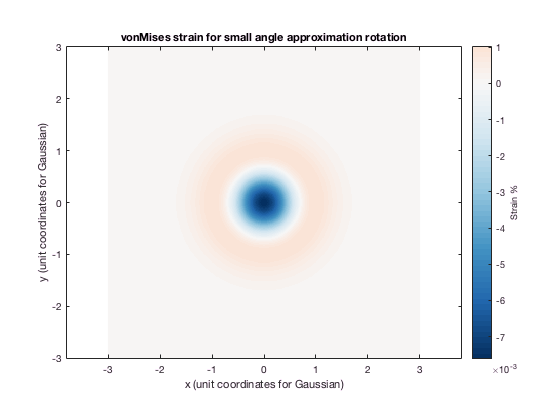

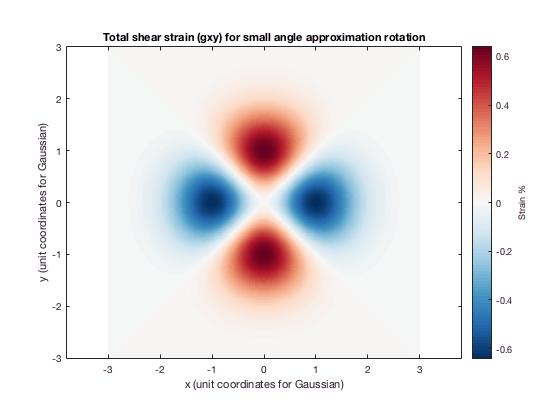

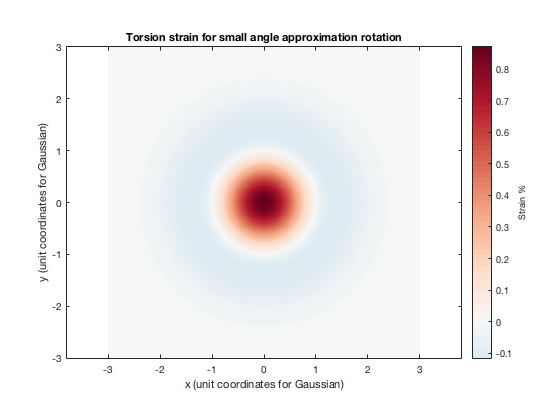

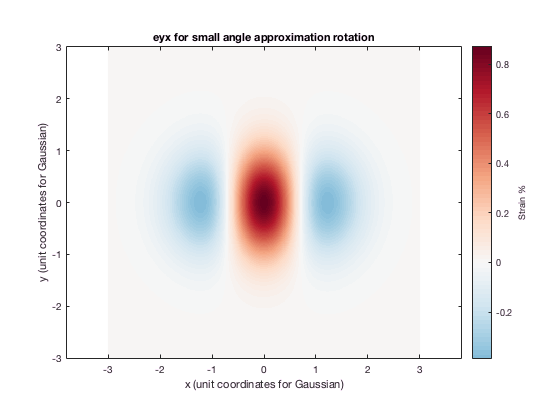

% Nothing done to the yy strain
